#### **Linear Mixed Models**

**Load data.**  Put all the HDI results files into a structure where each field is a link density.

today = datestr(datetime("today"),'yymmdd'); % for saving files at the end
load("Data/bs_with_calculated_grmetrics_and_HDIs_w_paingen_250528.mat")

**Metadata predictor pre-processing**. Mean-centering, standardising variables.

% metadata with correct promis columns (merged in from final_12mo...)
meta_t1 = readtable("Data/240508_metadata_prepped.csv");
meta_t1 = meta_t1(meta_t1.time == 1, :) % subset T1

meta_t1 = 202×70 table
        URSI         time    id    group    panas_pa    panas_na      pcs       tsk11     sopa_emo    pgic    alcohol    opioid    cannabis    education    ethnicity    hispanic    employment_status    exercise    handedness    sses    married_or_living_as_marri    age    weight    gender    current_opioid_use    backpain_length    spon_pain_rating_mean    spon_pain_ratings_1    spon_pain_ratings_2    spon_pain_ratings_3    spon_pain_ratings_4   


% % create masks for participants with high data qu ality & without too much head motion
% HC_motion_std = std(rmmissing(bs.subject_metadata(bs.subject_metadata.is_patient == 0,:).n_spike_regs_sponpain));
% cond1 = (bs.subject_metadata.n_spike_regs_sponpain > HC_motion_std*3)| bs.subject_metadata.is_patient == 0;
% cond2 = bs.subject_metadata.time == 1;
% cond3 = bs.data_quality.median_corr < std(bs.data_quality.median_corr)*3;
% % subset those participants
% wh_keep = cond1' & cond2' & cond3;
% 

% Define conditions
cond1 = bs.subject_metadata.time == 1;
cond2 = bs.data_quality.median_corr < std(bs.data_quality.median_corr) * 3;
HC_motion_std = std(rmmissing(bs.subject_metadata(bs.subject_metadata.is_patient == 0, :).n_spike_regs_sponpain));

% Initialize mask
wh_keep = false(size(cond1));

% Apply conditions based on which_model
which_model = 'outliers_only'; % all, no_outliers, outliers_only
if strcmp(which_model, 'all')
    % Keep all rows
    wh_keep = cond1' & cond2;
elseif strcmp(which_model, 'no_outliers')
    % Exclude motion outliers
    cond3 = (bs.subject_metadata.n_spike_regs_sponpain < HC_motion_std * 3) | bs.subject_metadata.is_patient == 0;
    wh_keep = cond1' & cond2 & cond3';
elseif strcmp(which_model, 'outliers_only')
    % Keep only outliers
    cond3 = (bs.subject_metadata.n_spike_regs_sponpain > HC_motion_std * 3) | bs.subject_metadata.is_patient == 0;
    wh_keep = cond1' & cond2 & cond3';
end

% wh_keep = cond2' & cond3
meta_bs = bs.subject_metadata(wh_keep,:);
% add row_index to sort after merging the new promis data
meta_bs.row_index = (1:height(meta_bs))';


% columns to be taken from the correct T1 covars metadata
cols = {'id', 'is_patient', 'age', 'gender', 'backpain_length', 'n_spike_regs_sponpain',...
    'negative_affect_t1', 'promis_sleep_t1', 'bpi_intensity_t1', 'bpi_interference_t1', 'odi_t1'};
% merge bs meta and correct T1 metadata
X = outerjoin(meta_bs(:, {'id', 'row_index'}), meta_t1(:, cols), 'Type','Left', 'Keys','id', 'MergeKeys', true);
% sort rows by row_index => same ordering as the whole bs structure
X = sortrows(X, 'row_index');
% remove the row_index column
X.row_index = [];

% betweenness_vals = hdis.link_dens_4.betweenness_bin(wh_keep)
% figure
% scatter(X.bpi_interference_t1, X.odi_t1, [], betweenness_vals, 'filled')
% hex_codes = {'#3381FF', '#d3d3d3', '#FF5733'};
% rgb_values = sscanf(cat(2, hex_codes{:}), '#%2x%2x%2x', [3, numel(hex_codes)])' / 255;
% custom_colormap = interp1(linspace(0, 1, numel(hex_codes)), rgb_values, linspace(0, 1, 256));
% colormap(custom_colormap)
% c = colorbar;
% 
% % Add labels
% ylabel(c, 'betweenness HDI');
% xlabel('BPI interference');
% ylabel('ODI');

% tidy up vars
X.age = X.age - nanmean(X.age);
X.gender = X.gender - 1.5;
X.backpain_length(X.is_patient==0) = 0; % 0 for healthy controls; no back pain

% mean-center pain within group, within time point. This way it is not correlated with group or time
vars_to_centre = {'backpain_length', 'n_spike_regs_sponpain', 'promis_sleep_t1', 'negative_affect_t1',...
    'bpi_intensity_t1', 'bpi_interference_t1', 'odi_t1'};

for is_patient = [true, false]
    cohort = X.is_patient == is_patient;
    for var = vars_to_centre
        X{cohort, var{1}} = X{cohort, var{1}} - nanmean(X{cohort, var{1}});
    end
end

% standardize all vars except for the categorical ones
vars_to_scale = ['age', vars_to_centre];
for var = vars_to_scale
    X.(var{1}) = scale(X.(var{1}));
end

**Run the LMMs. **Within metric, across all link densities - this will be compiled together into a single heatmap.

metrics = {'degree', 'betweenness_bin', 'clustercoef_bin', 'local_efficiency_bin', 'eigenvector_centrality_bin'};
m=2

m = 2

threshs = fieldnames(hdis);
y = [];
for thr=1:length(threshs)
    y(:,thr) = hdis.(threshs{thr}).(metrics{m})(wh_keep);
end

if istable(y), y = table2array(y); end
    cbp_vs_hc = struct(); % create an empty output structure
    for i=1:size(y,2)
        X.y = y(:,i);
        X.y = scale(X.y);
        
        X.is_HC = ~X.is_patient;
        analysis_str = ['y ~ 1 + age + gender + is_HC + backpain_length + n_spike_regs_sponpain + ' ...
            'promis_sleep_t1 + negative_affect_t1 + bpi_intensity_t1 + odi_t1'];
        lme_cbp_vs_hc = fitlme(X, analysis_str, 'DummyVarCoding', 'reference', 'FitMethod', 'REML'); 
        [b, bnames, festats_cbp_vs_hc] = fixedEffects(lme_cbp_vs_hc, 'DFMethod', 'Satterthwaite');

        if i==1, cbp_vs_hc.names = festats_cbp_vs_hc.Name; end % set names on first iteration
        cbp_vs_hc.tStat(:, i) = festats_cbp_vs_hc.tStat;
        cbp_vs_hc.p(:, i) = festats_cbp_vs_hc.pValue;
        cbp_vs_hc.beta(:, i) = festats_cbp_vs_hc.Estimate;
    end


% Extracting data
t_statistics = cbp_vs_hc.tStat;
t_statistics(abs(t_statistics) < 1.9) = NaN;



T1 = table(cbp_vs_hc.names)
T1.degree_at_30p = t_statistics(:, 3)
T1.btwn_at_30p = t_statistics(:, 3)
writetable(T1, 'Data/t_stats_for_INDprezi_out_only.csv');


% Define RGB values for the given hex codes
hex_codes = {'#3381FF', '#FFFFFF', '#FF5733'};
rgb_values = sscanf(cat(2, hex_codes{:}), '#%2x%2x%2x', [3, numel(hex_codes)])' / 255;
custom_colormap = interp1(linspace(0, 1, numel(hex_codes)), rgb_values, linspace(0, 1, 256));

max_abs_value = max(abs(t_statistics), [], 'all');

% Creating heatmap
figure;
heatmap(regexprep(cbp_vs_hc.names, '_', '\\_'), 1:size(t_statistics, 2), t_statistics', 'ColorLimits', [-max_abs_value, max_abs_value], 'MissingDataColor', [1 1 1]);

% Customizing heatmap
colormap(custom_colormap); % You can change the colormap if needed
colorbar;

% Setting axis labels and title
xlabel('');
ylabel('Link density');
title_text = regexprep(['T Stats: ' metrics{m}], '_', '\\_')

title_text = 'T Stats Heatmap of CBP vs HC - betweenness\_bin'

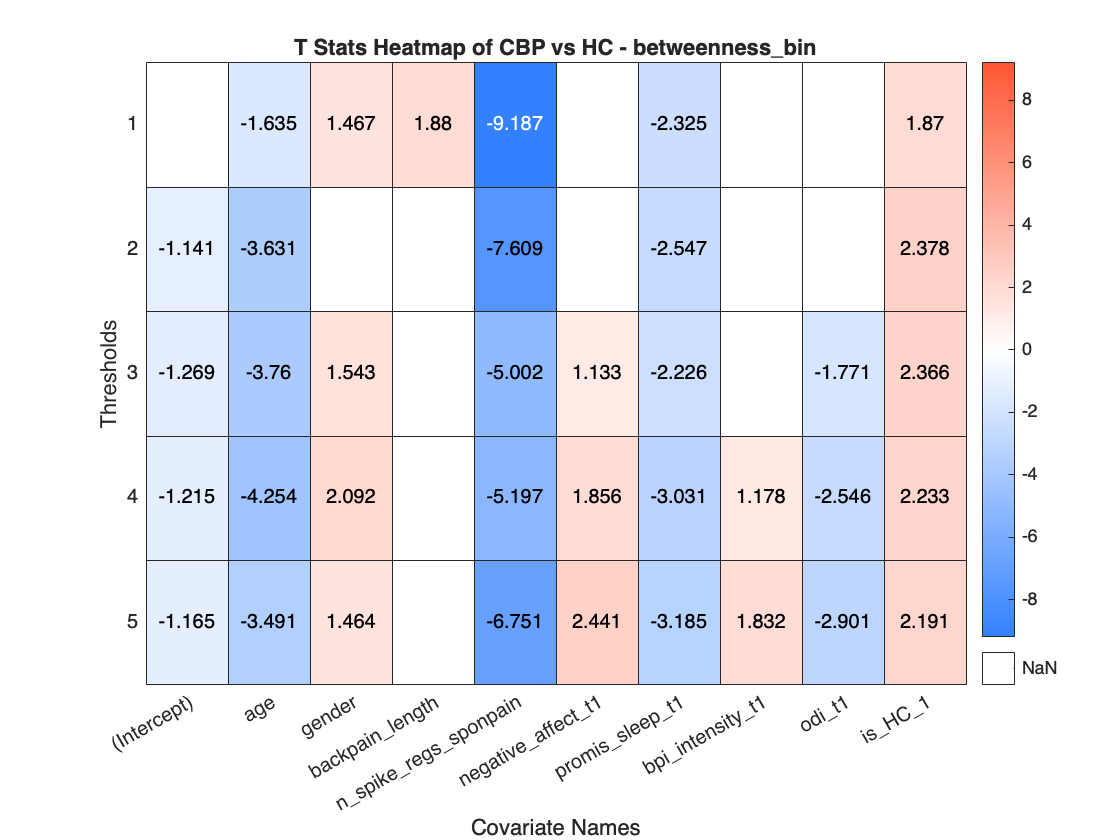

title(title_text);


filename = ['Graphs/paingen LMM/' today '_CBP vs HC_' metrics{m} '_3sd_head_motion_CBP_vs_HC.png'];
print(gcf, filename, '-dpng', '-r300');

Plotting pain avg after mean centering

X.is_patient_cat = categorical(X.is_patient, [0 1], {'HC' 'CBP'}, 'Ordinal', false);

grpandplot(X, "pain_avg", cFactor="is_patient_cat")
title('Average pain in groups (after mean centering within group)');

